# Initial tests

## Comments and variables

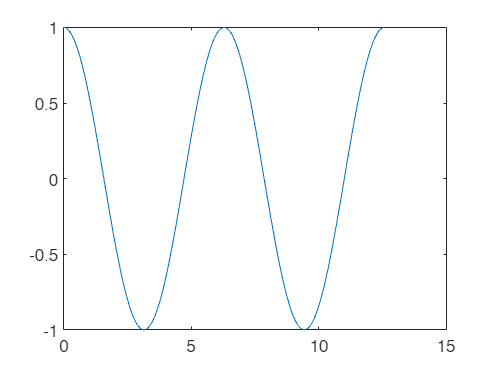


% This is a comment
x = deg2rad(1:2:2 * 360);
y = cos(x);
cos_plot = plot(x, y);

## Indexing and slicing

z = 1:200;
w = z(7:2:200);
w(3:35) = 3:35; % Must be same length.

## Functions

function [num_steps] = randomwalk(starting_distance)
    num_steps = 0;
    while starting_distance ~= 0
        if randi(2, 1, 1) == 1
            starting_distance = starting_distance - 1;
        else
            starting_distance = starting_distance + 1;
        end
        num_steps = num_steps + 1;
    end
end

## Loops

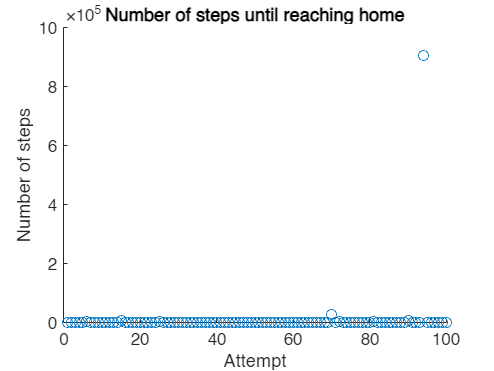

randi(30, 900, 1);
numFlips(1:100) = 0;
for i = 1:100
    numFlips(i) = randomwalk(3);
end

numFlips;

scatterplot_numFlips = scatter(1:100, numFlips);
title("Number of steps until reaching home")
xlabel("Attempt")
ylabel("Number of steps")


mean_numFlips = mean(numFlips)

mean_numFlips = 9.5822e+03

median_numFlips = median(numFlips)

median_numFlips = 28

## Random

n = randi(2, 1, 1);

## Quivers

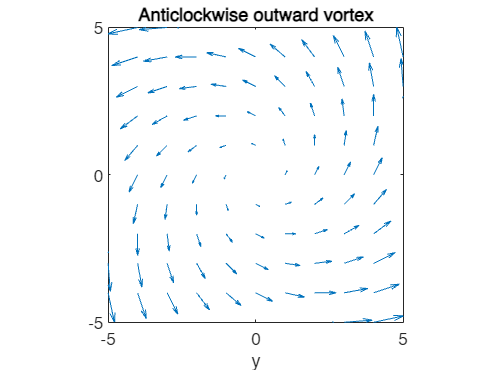

% Variables
a = 2; b = 4; c = -3;
range = 5;

% 2D quiver
x = -range:range;
y = x;
[X, Y] = meshgrid(x, y);

U = a * X - b * Y; V = b * X + a * Y;
quiver(X, Y, U, V)
axis equal
title("Anticlockwise outward vortex")
xlabel("x")
xlabel("y")
xlim([-range, range])
ylim([-range, range])

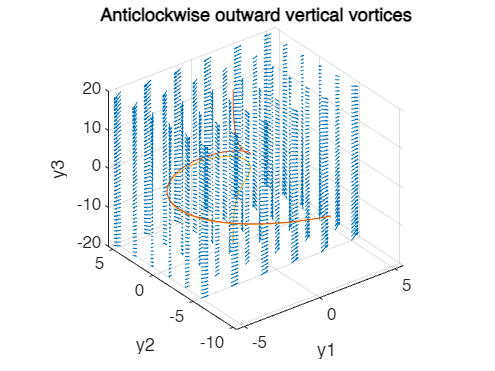


% 3D quiver
range = 5;
step = 2;
zrange = 20;
zstep = step .* zrange / range;
scaling = 0.75;

x = -range:step:range; y = x; z = -zrange:zrange / 20:zrange;
[X, Y, Z] = meshgrid(x, y, z);

U = a * X - b * Y; V = b * X + a * Y; W = c * Z;

M = [a -b 0; b a 0; 0 0 c];

quiver3(X, Y, Z, U, V, W, scaling)
title("Anticlockwise outward vertical vortices")
xlabel("y1")
ylabel("y2")
zlabel("y3")
pbaspect([1, 1, 0.85])

hold on
% Parametrized solution
t = -1:0.01:1;
x = exp(1).^(a * t) .* (cos(b * t) - sin(b * t));
y = exp(1).^(a * t) .* (sin(b * t) + cos(b * t));
z = exp(1).^(c * t);
plot3(x, y, z)

hold on
t = -1:0.01:1;
x = exp(1).^(a * t) .* (cos(b * t) - sin(b * t));
y = exp(1).^(a * t) .* (sin(b * t) + cos(b * t));
z = -exp(1).^(c * t);
plot3(x, y, z)
hold off

## Parametric curves

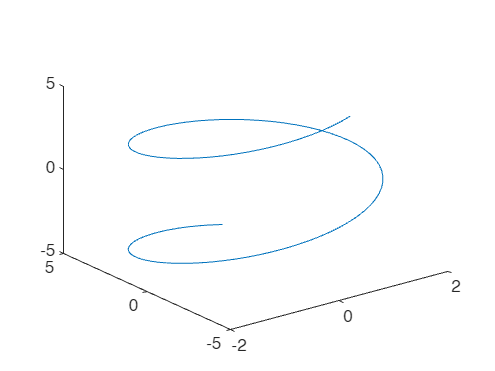

t = -5:0.1:5;
z = t; x = a * cos(t); y = b * sin(t);

plot3(x, y, z)

## Matrix multiplication

A = [1 2 3; 4 5 6; 7 8 9;]

A =      1     2     3
     4     5     6
     7     8     9


vect = [1 2 3]

vect =      1     2     3


vect = transpose(vect)

vect =      1
     2
     3


A_vect = A * vect

A_vect =     14
    32
    50


threeVect = 3 * vect

threeVect =      3
     6
     9
